Question 1: 

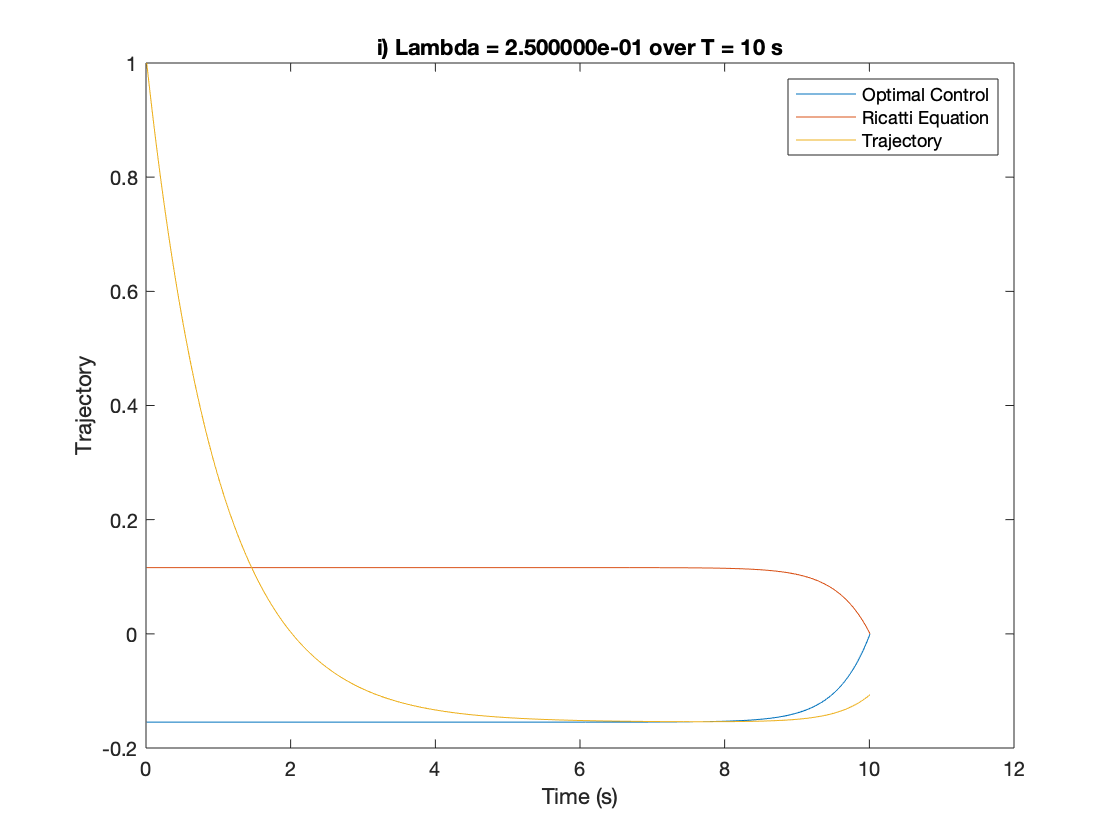

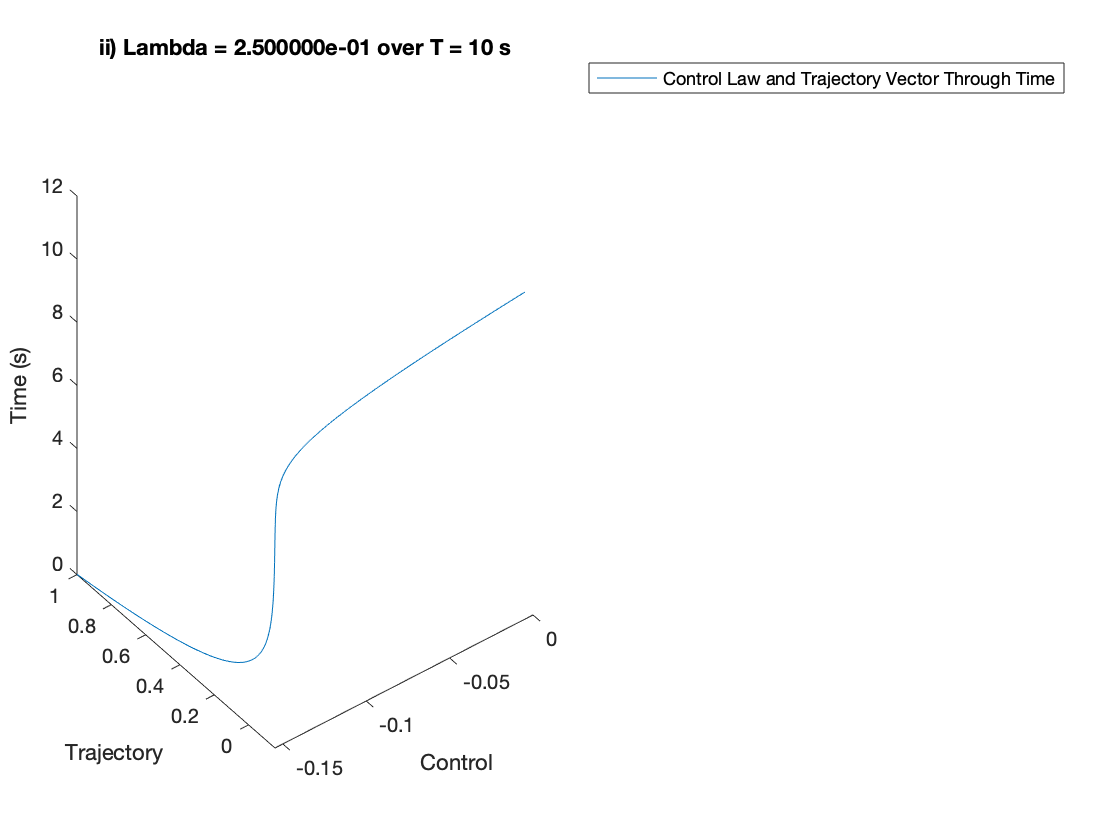

% Question 1

%Case 1
l1 = 1/4;
T1 = 10;
plot_ricc_traj(l1,T1)

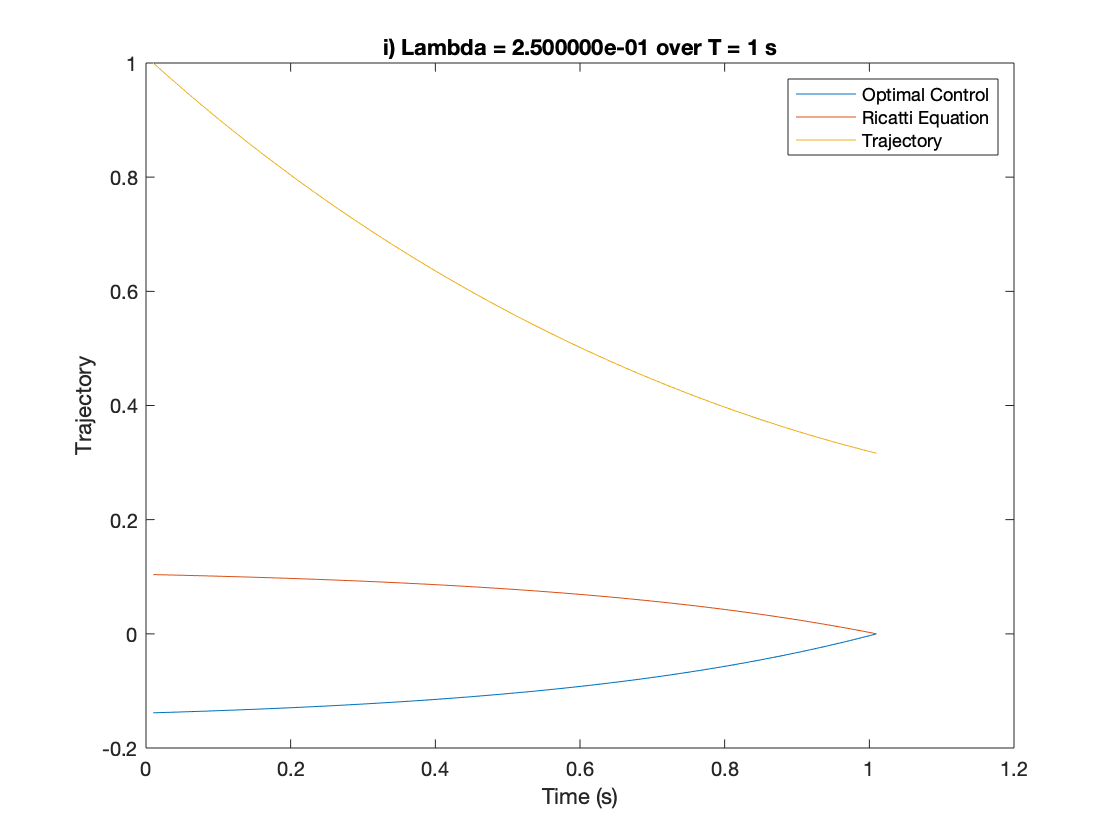

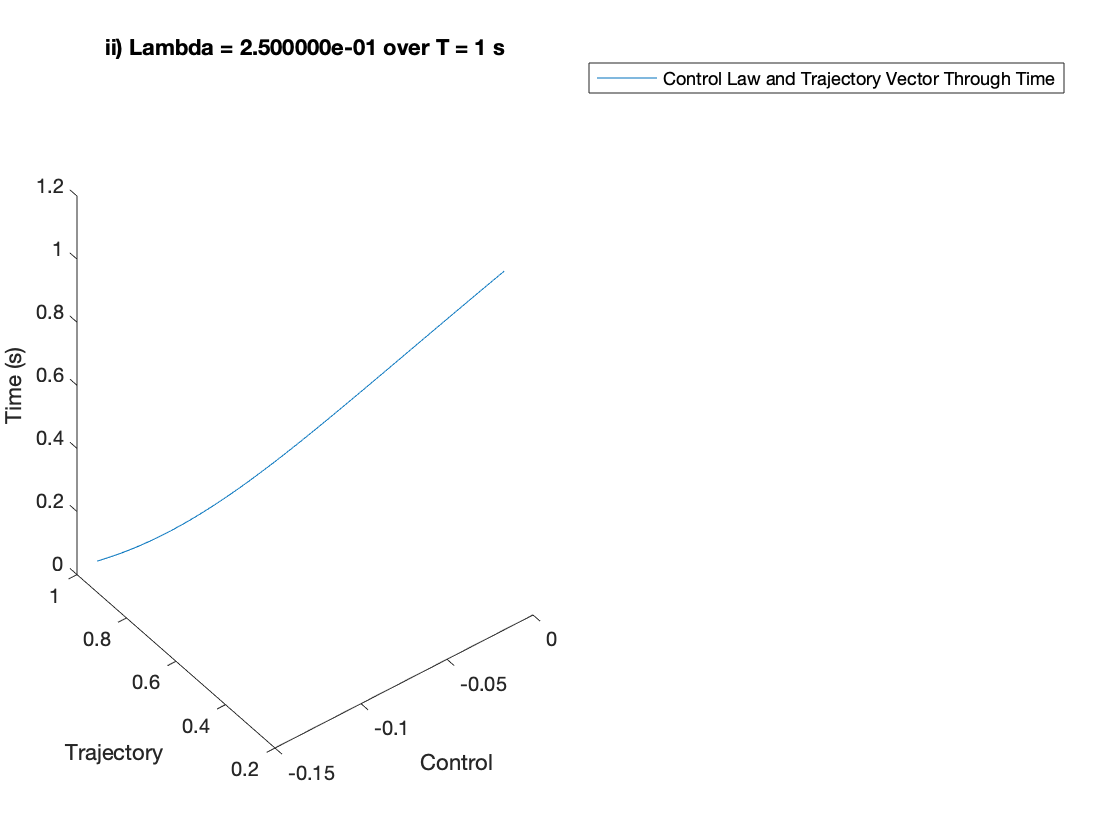


%Case 2
l1 = 1/4;
T2 = 1;
plot_ricc_traj(l1,T2)

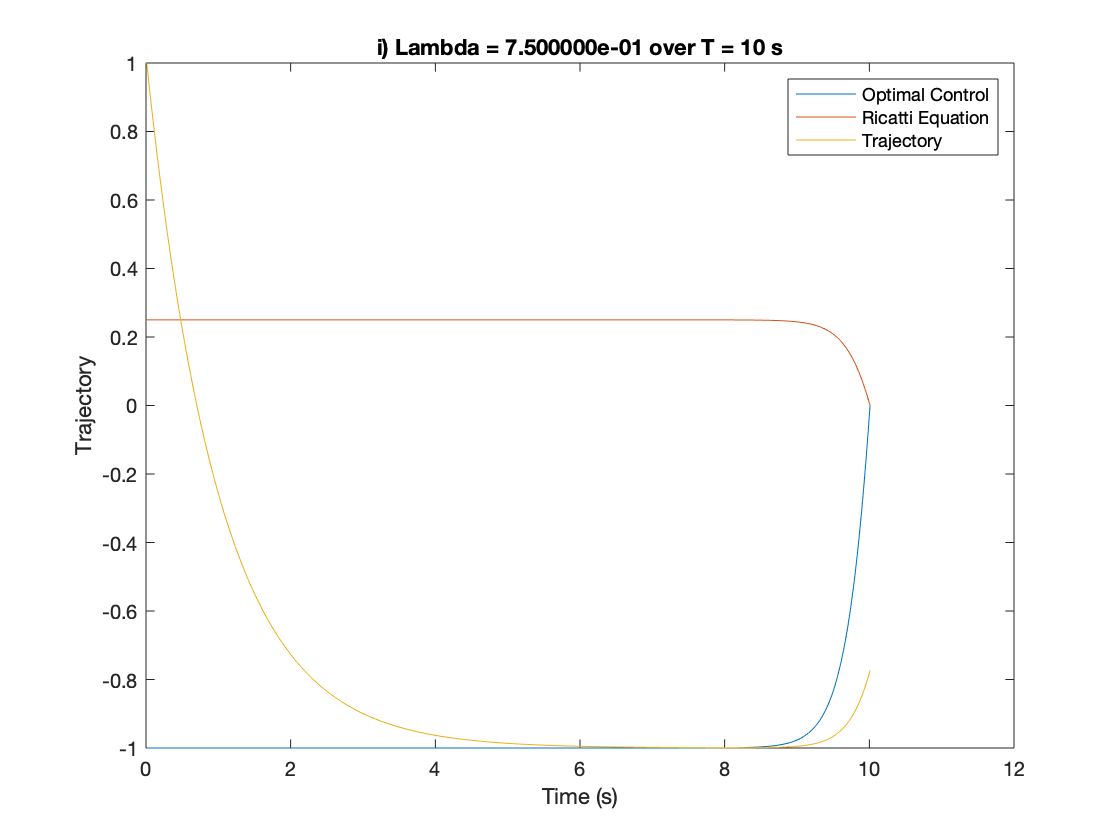

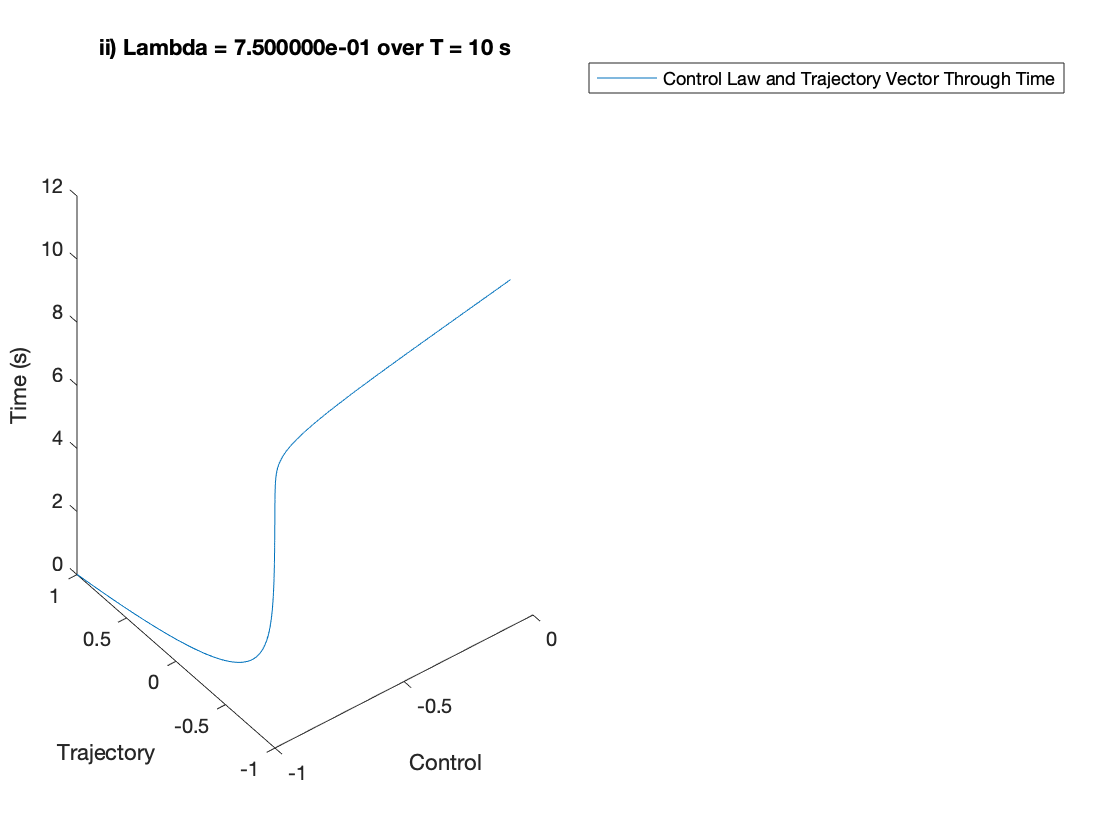


%Case 3
l2 = 3/4;
T1 = 10;
plot_ricc_traj(l2,T1)

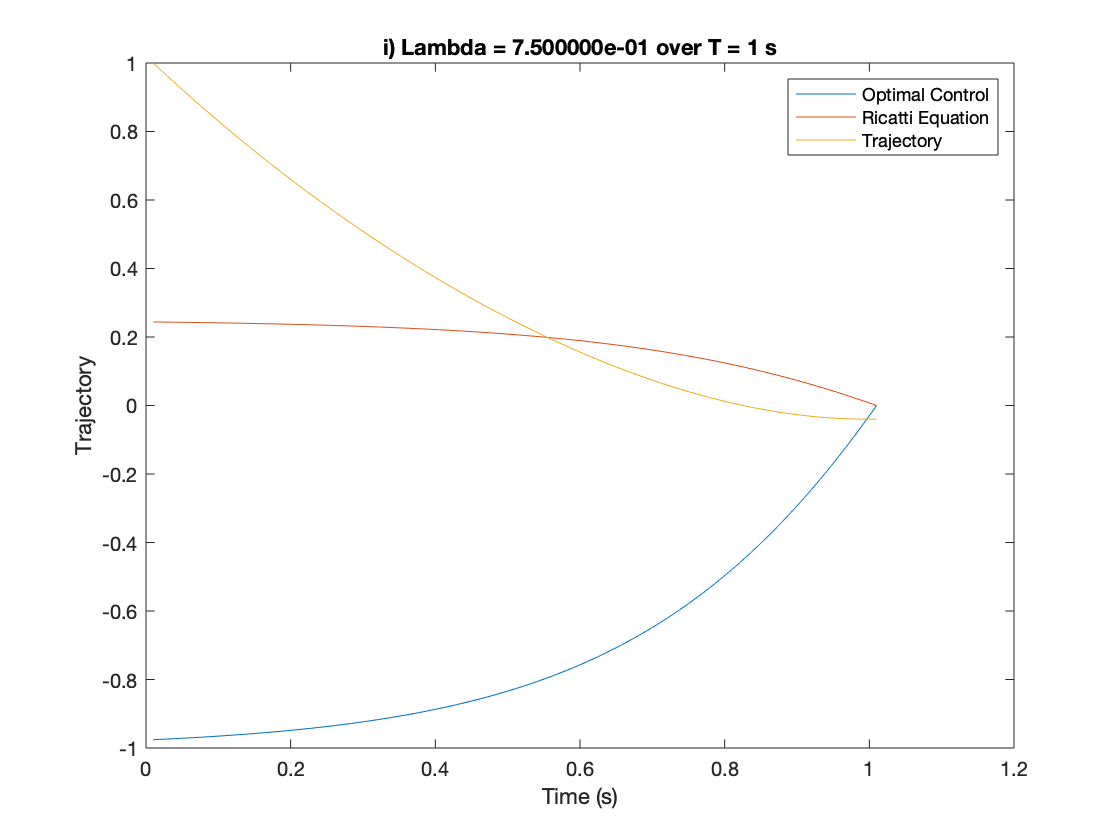

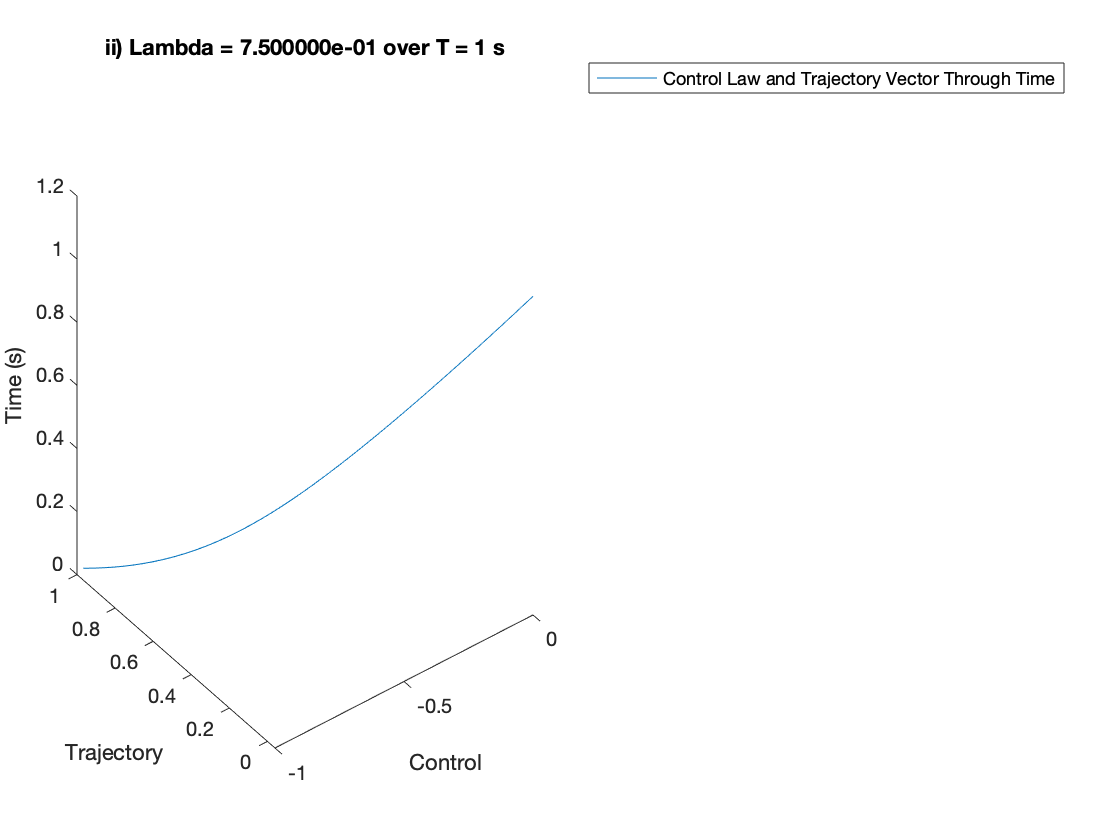


%Case 1
l2 = 3/4;
T2 = 1;
plot_ricc_traj(l2,T2)

Question 2: 

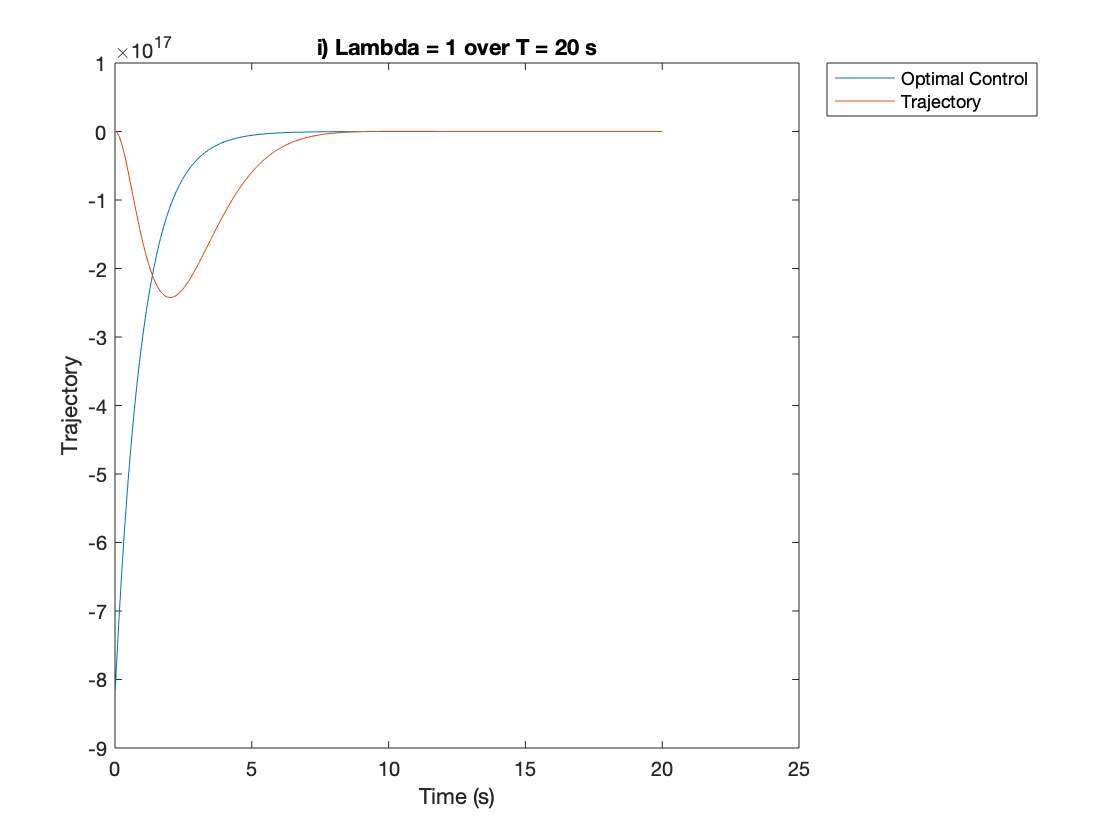

l = 1;
plot_control(1)

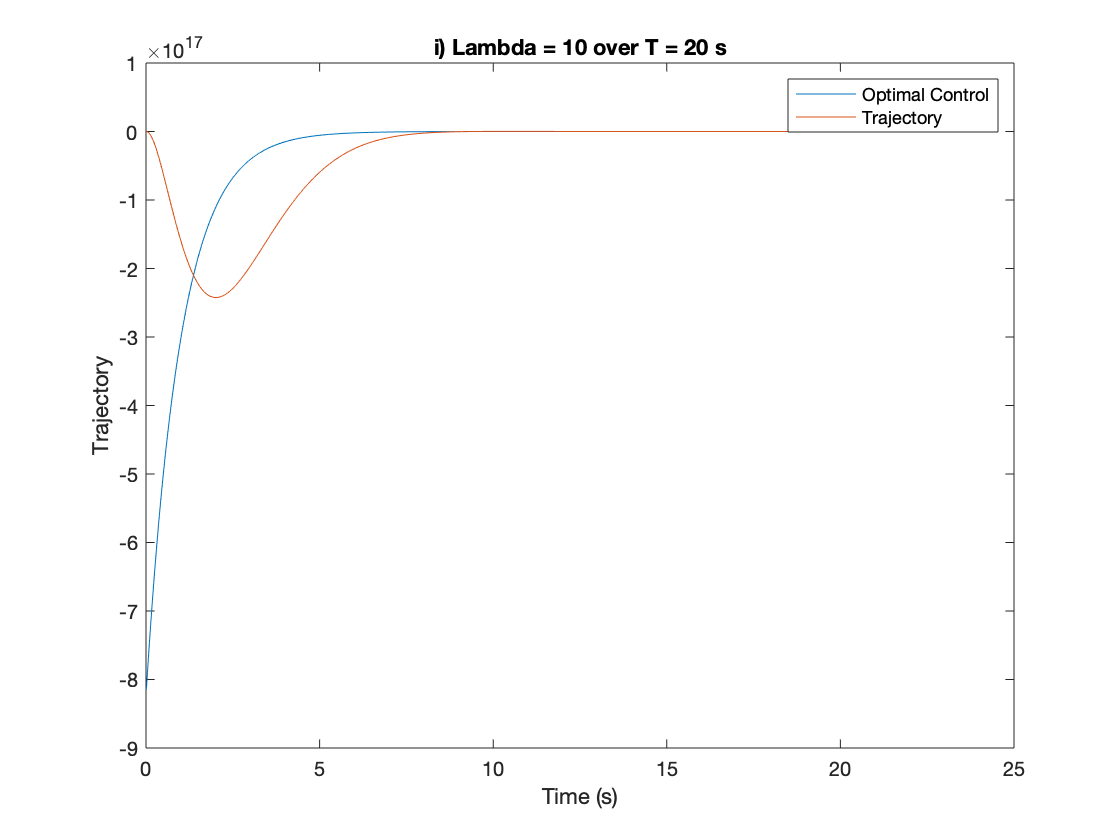


l = 10;
plot_control(10)

function plot_control(l)
alpha = 1;
x0 = [1; 1];
T = 20;
t = 0;
A = [0 1; -1 -sqrt(alpha + 2)];
B = [0; 1];
C = [1 0]; 

e = sqrt(1-l);
e = sqrt(1-l);
i = 1;
kt = [];
u = [];
Gramian = 0;
sqrt(1-10) - (1-10);
dt = 0.01;
for t=0:dt:20
    kt(i) = e*((1 + e)+(e-1)*exp(2*(t-20)/e))/((1 + e)-(e-1)*exp(2*(t-20)/e)) - e^2;
    u(i) = -1/(1-l)*kt(i);
    i = i + 1;
    Gramian = Gramian + expm(A * (T - i*dt)) * B * transpose(B) * expm(transpose(A) * (T - i * dt))*dt;
end

i = 1;
for t=0:dt:20
    u(i) = [exp(T-t) exp(-2*(T-t))] * inv(Gramian) * [2-exp(T); -1-exp(-2*(T))];
    i = i + 1; 
end

sys = ss(A, B, C, 0);
x = lsim(sys,u,dt:dt:(T+dt),x0);


figure(5)
plot(dt:dt:20.01, u);
hold on;
plot(dt:dt:20.01, x)
hold off;

legend('Optimal Control','Trajectory');
tit = 'i) Lambda = %d over T = %d s';
title(sprintf(tit,l,T));
xlabel('Time (s)') 
ylabel('Trajectory')

end
function plot_ricc_traj(l,T)

e = sqrt(1-l);

kt = [];
u = [];
i = 1;
dt = 0.01;
x0 = 1;
for t = 0:dt:T
    kt(i) = e*((1 + e)+(e-1)*exp(2*(t-T)/e))/((1 + e)-(e-1)*exp(2*(t-T)/e)) - e^2;
    u(i) = -1/(1-l)*kt(i);
    x(i) = exp(-t)*x0 - exp(-t)*u(i);
    i = i+1;
end


A = -1;
B = 1;
C = 1;
sys = ss(A, B, C, 0);
x = lsim(sys,u,dt:dt:(T+dt),x0);

figure(1)
plot(dt:dt:(T+dt), u);
hold on;
plot(dt:dt:(T+dt), kt)
hold on;
plot(dt:dt:(T+dt), x)
hold off;
legend('Optimal Control','Ricatti Equation','Trajectory');
tit = 'i) Lambda = %d over T = %d s';
title(sprintf(tit,l,T));
xlabel('Time (s)') 
ylabel('Trajectory')

figure(5)
plot3(u,x,dt:dt:(T+dt))
legend('Control Law and Trajectory Vector Through Time');
tit = 'ii) Lambda = %d over T = %d s';
title(sprintf(tit,l,T));
xlabel('Control') 
ylabel('Trajectory')
zlabel('Time (s)')

end
